# Robot Esférico

clc; clear; close all;

%% ==========================================================
%  BLOQUE 1: ANÁLISIS SIMBÓLICO: ROBOT ESFÉRICO (RRP)
%  ==========================================================
disp("=== ANÁLISIS SIMBÓLICO: ROBOT ESFÉRICO (RRP) ===")

=== ANÁLISIS SIMBÓLICO: ROBOT ESFÉRICO (RRP) ===



% Variables simbólicas
syms q1 q2 d3 l1 beta1 beta2 real 

% --- 1. Eslabón 1 (Revoluta Z, Rotación -90 X) ---
H1_0_sym = simplify( Hrz(q1) * Htz(l1+beta1) * Htx(0) * round(Hrx(-90)) );
disp(">>> Matriz H1_0:"); disp(H1_0_sym);

>>> Matriz H1_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & \beta_{1}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 2. Eslabón 2 (Revoluta Z, Rotación 90 X) ---
H2_1_sym = simplify( Hrz(q2) * Htz(beta2) * Htx(0) * round(Hrx(90)) );
H2_0_sym = simplify( H1_0_sym * H2_1_sym );
disp(">>> Matriz H2_0:"); disp(H2_0_sym);

>>> Matriz H2_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\beta_{2}\,\sin\left(q_{1}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \beta_{2}\,\cos\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \beta_{1}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 3. Eslabón 3 (Prismático Z) ---
H3_2_sym = simplify( Hrz(0) * Htz(d3) * Htx(0) * round(Hrx(0)) );
H3_0_sym = simplify( H2_0_sym * H3_2_sym );
Pf_sym = [H3_0_sym(1,4); H3_0_sym(2,4); H3_0_sym(3,4)];
disp(">>> Matriz Final H3_0:"); disp(H3_0_sym);

>>> Matriz Final H3_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\beta_{2}\,\sin\left(q_{1}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \beta_{2}\,\cos\left(q_{1}\right)+d_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \beta_{1}+l_{1}+d_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- Cinemática Diferencial ---
disp("--- CINEMÁTICA DIFERENCIAL ---")

--- CINEMÁTICA DIFERENCIAL ---


J_sym = simplify(jacobian(Pf_sym, [q1, q2, d3]));
Det_J_sym = simplify(det(J_sym));
disp(">>> Matriz Jacobiana (3x3):"); disp(J_sym);

>>> Matriz Jacobiana (3x3):


$$\left(\begin{array}{ccc} -\beta_{2}\,\cos\left(q_{1}\right)-d_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ d_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\beta_{2}\,\sin\left(q_{1}\right) & d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & -d_{3}\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

disp(">>> Determinante de la Jacobiana:"); disp(Det_J_sym);

>>> Determinante de la Jacobiana:


$$-{d_{3}}^{2}\,\sin\left(q_{2}\right)$$



%% ==========================================================
%  BLOQUE 2: ROBOT 1 (Apuntando Arriba-Derecha)
%  ==========================================================
disp("=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===


% Parámetros físicos (Notar que l2 y l3 son cero en DH para este robot)
r1_l1 = 0.5; r1_b1 = 0.1; r1_b2 = 0.15; 
r1_q1 = deg2rad(45); r1_q2 = deg2rad(30); r1_d3 = 0.6; % Extensión

sym_vars = [q1, q2, d3, l1, beta1, beta2];
vals_R1  = [r1_q1, r1_q2, r1_d3, r1_l1, r1_b1, r1_b2];

% Evaluaciones Numéricas
H1_R1 = double(subs(H1_0_sym, sym_vars, vals_R1)); S1_R1 = H1_R1(1:3, 4);
H2_R1 = double(subs(H2_0_sym, sym_vars, vals_R1)); S2_R1 = H2_R1(1:3, 4);
H3_R1 = double(subs(H3_0_sym, sym_vars, vals_R1)); Pf_R1 = H3_R1(1:3, 4);

disp("Punto Final Pf_R1 (X, Y, Z):"); disp(Pf_R1');

Punto Final Pf_R1 (X, Y, Z):
    0.1061    0.3182    1.1196



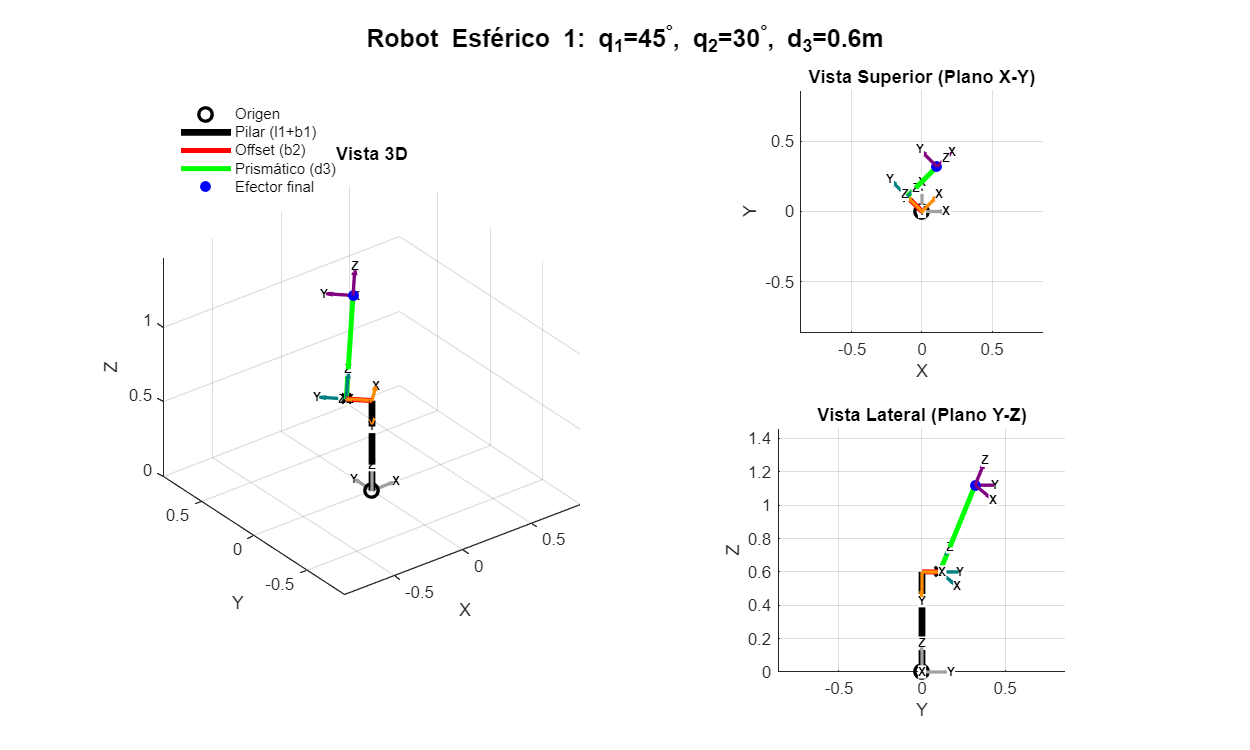


L_max1 = r1_d3 + r1_b2; % El radio máximo de la esfera de alcance
figure('Name', 'Robot Esférico 1', 'Position', [50, 100, 1000, 600]);
sgtitle(['Robot Esférico 1: q_1=' num2str(rad2deg(r1_q1)) '^\circ, q_2=' num2str(rad2deg(r1_q2)) '^\circ, d_3=' num2str(r1_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg = plotRobotEsferico(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1, r1_l1+r1_b1);
view(3); title('Vista 3D');
legend([h_leg.orig, h_leg.pilar, h_leg.b2, h_leg.e3, h_leg.pf], ...
       {'Origen', 'Pilar (l1+b1)', 'Offset (b2)', 'Prismático (d3)', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotEsferico(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1, r1_l1+r1_b1);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotEsferico(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1, r1_l1+r1_b1);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, qi2, di3] = cinv_Esferico(r1_l1, r1_b1, r1_b2, Pf_R1(1), Pf_R1(2), Pf_R1(3));
disp("Cinemática Inversa R1 (q1, q2, d3):"); disp([qi1, qi2, di3]);

Cinemática Inversa R1 (q1, q2, d3):
   45.0000   30.0000    0.6000





%% ==========================================================
%  BLOQUE 3: ROBOT 2 (Apuntando casi horizontal, cuadrante 2)
%  ==========================================================
disp("=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===


r2_l1 = 0.7; r2_b1 = 0.05; r2_b2 = 0.2; 
r2_q1 = deg2rad(135); r2_q2 = deg2rad(80); r2_d3 = 0.8; 

vals_R2  = [r2_q1, r2_q2, r2_d3, r2_l1, r2_b1, r2_b2];

H1_R2 = double(subs(H1_0_sym, sym_vars, vals_R2)); S1_R2 = H1_R2(1:3, 4);
H2_R2 = double(subs(H2_0_sym, sym_vars, vals_R2)); S2_R2 = H2_R2(1:3, 4);
H3_R2 = double(subs(H3_0_sym, sym_vars, vals_R2)); Pf_R2 = H3_R2(1:3, 4);

disp("Punto Final Pf_R2 (X, Y, Z):"); disp(Pf_R2');

Punto Final Pf_R2 (X, Y, Z):
   -0.6985    0.4157    0.8889



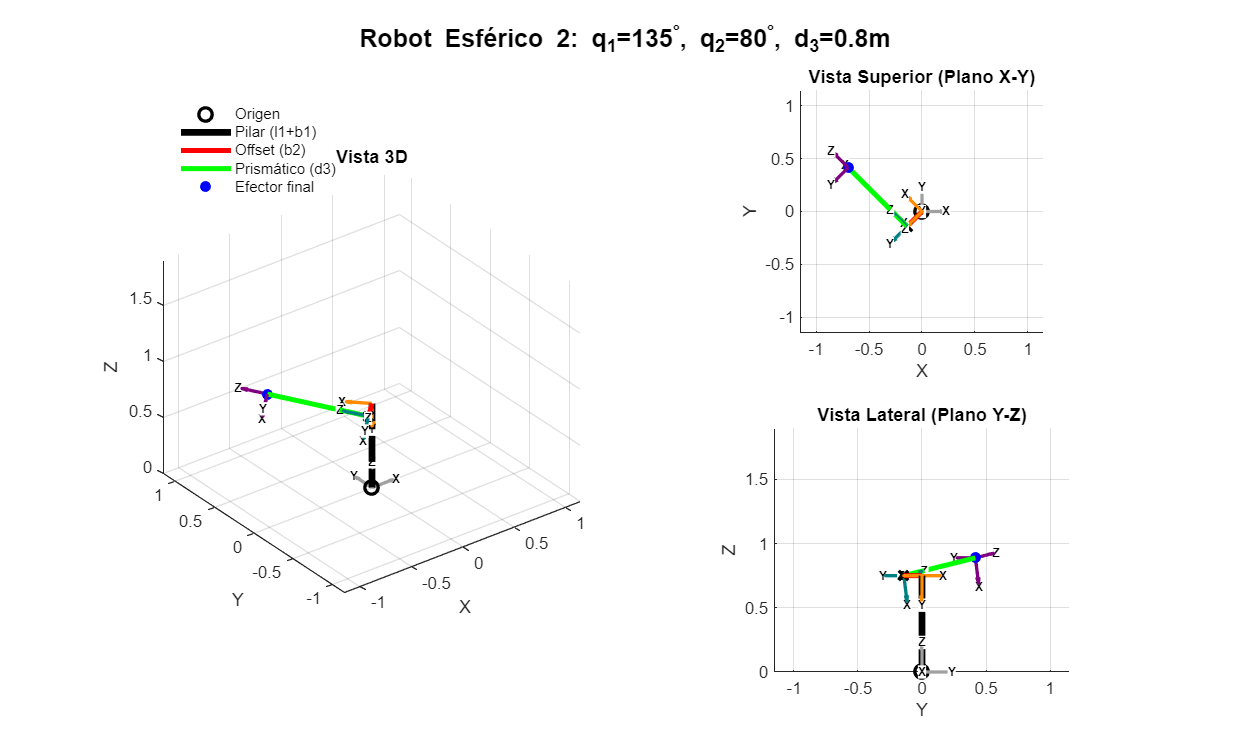


L_max2 = r2_d3 + r2_b2;
figure('Name', 'Robot Esférico 2', 'Position', [100, 150, 1000, 600]);
sgtitle(['Robot Esférico 2: q_1=' num2str(rad2deg(r2_q1)) '^\circ, q_2=' num2str(rad2deg(r2_q2)) '^\circ, d_3=' num2str(r2_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg2 = plotRobotEsferico(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2, r2_l1+r2_b1);
view(3); title('Vista 3D');
legend([h_leg2.orig, h_leg2.pilar, h_leg2.b2, h_leg2.e3, h_leg2.pf], ...
       {'Origen', 'Pilar (l1+b1)', 'Offset (b2)', 'Prismático (d3)', 'Efector final'}, 'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotEsferico(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2, r2_l1+r2_b1);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotEsferico(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2, r2_l1+r2_b1);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, qi2, di3] = cinv_Esferico(r2_l1, r2_b1, r2_b2, Pf_R2(1), Pf_R2(2), Pf_R2(3));
disp("Cinemática Inversa R2 (q1, q2, d3):"); disp([qi1, qi2, di3]);

Cinemática Inversa R2 (q1, q2, d3):
  135.0000   80.0000    0.8000





%% ==========================================================
%  BLOQUE 4: ROBOT 3 (Apuntando Abajo, cuadrante 3)
%  ==========================================================
disp("=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===


r3_l1 = 0.8; r3_b1 = 0; r3_b2 = 0.1; 
r3_q1 = deg2rad(-120); r3_q2 = deg2rad(120); r3_d3 = 0.5; 

vals_R3  = [r3_q1, r3_q2, r3_d3, r3_l1, r3_b1, r3_b2];

H1_R3 = double(subs(H1_0_sym, sym_vars, vals_R3)); S1_R3 = H1_R3(1:3, 4);
H2_R3 = double(subs(H2_0_sym, sym_vars, vals_R3)); S2_R3 = H2_R3(1:3, 4);
H3_R3 = double(subs(H3_0_sym, sym_vars, vals_R3)); Pf_R3 = H3_R3(1:3, 4);

disp("Punto Final Pf_R3 (X, Y, Z):"); disp(Pf_R3');

Punto Final Pf_R3 (X, Y, Z):
   -0.1299   -0.4250    0.5500



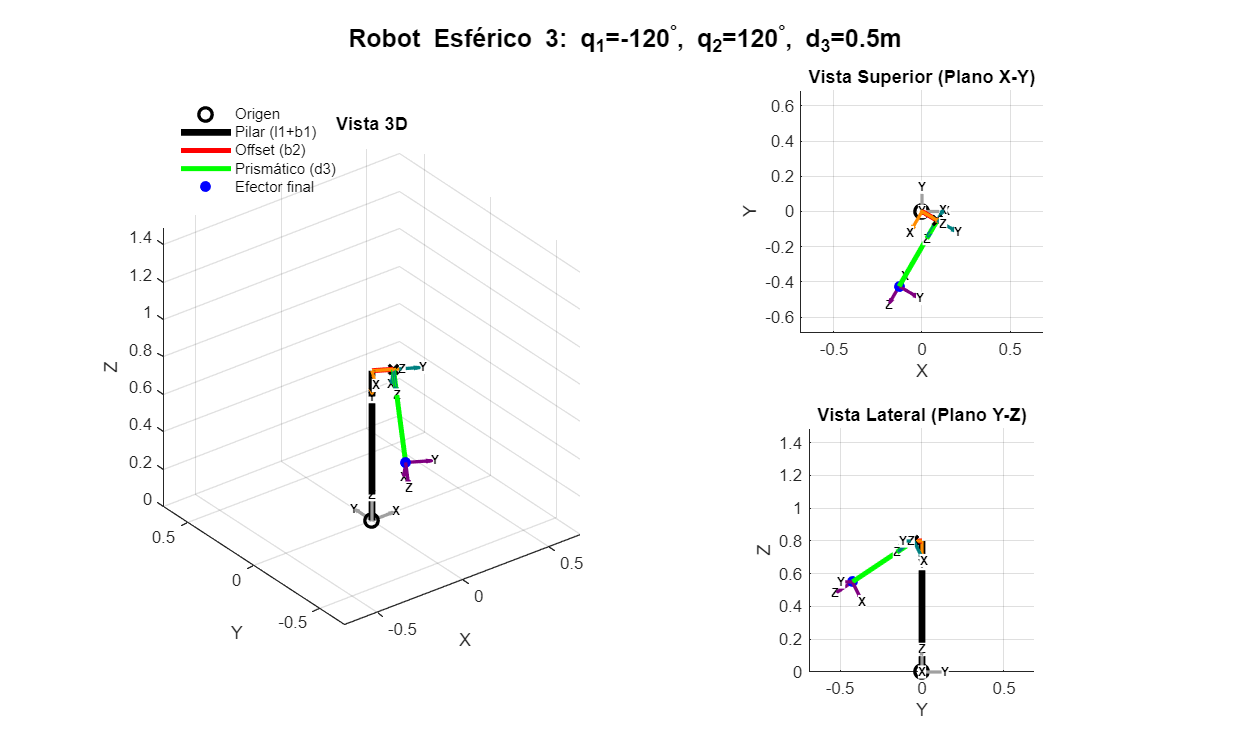


L_max3 = r3_d3 + r3_b2;
figure('Name', 'Robot Esférico 3', 'Position', [150, 200, 1000, 600]);
sgtitle(['Robot Esférico 3: q_1=' num2str(rad2deg(r3_q1)) '^\circ, q_2=' num2str(rad2deg(r3_q2)) '^\circ, d_3=' num2str(r3_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg3 = plotRobotEsferico(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3, r3_l1+r3_b1);
view(3); title('Vista 3D');
legend([h_leg3.orig, h_leg3.pilar, h_leg3.b2, h_leg3.e3, h_leg3.pf], ...
       {'Origen', 'Pilar (l1+b1)', 'Offset (b2)', 'Prismático (d3)', 'Efector final'}, 'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotEsferico(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3, r3_l1+r3_b1);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotEsferico(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3, r3_l1+r3_b1);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, qi2, di3] = cinv_Esferico(r3_l1, r3_b1, r3_b2, Pf_R3(1), Pf_R3(2), Pf_R3(3));
disp("Cinemática Inversa R3 (q1, q2, d3):"); disp([qi1, qi2, di3]);

Cinemática Inversa R3 (q1, q2, d3):
 -120.0000  120.0000    0.5000





%% ==========================================================
%  FUNCION LOCAL DE GRAFICACIÓN ESFÉRICO
%  ==========================================================

function h = plotRobotEsferico(S1, S2, Pf, H1, H2, H3, L_max, AlturaPilar)
    hold on; grid on; axis equal;
    
    % Origen
    h.orig = plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Pilar Central (Asciende por Z hasta S1)
    h.pilar = plot3([0, S1(1)], [0, S1(2)], [0, S1(3)], 'k', 'LineWidth', 4);
    
    % Brazo de Offset (beta 2)
    h.b2 = plot3([S1(1), S2(1)], [S1(2), S2(2)], [S1(3), S2(3)], 'r', 'LineWidth', 3);
    plot3(S2(1), S2(2), S2(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Eslabón Prismático (Sale radialmente como cañón)
    h.e3 = plot3([S2(1), Pf(1)], [S2(2), Pf(2)], [S2(3), Pf(3)], 'g', 'LineWidth', 3); 
    h.pf = plot3(Pf(1), Pf(2), Pf(3), 'bo', 'MarkerFaceColor', 'b');
    
    % Límites dinámicos ajustados al radio de la esfera
    lim_xy = L_max * 1.15; 
    lim_z  = AlturaPilar + (L_max * 1.15); 
    xlim([-lim_xy, lim_xy]); ylim([-lim_xy, lim_xy]); zlim([0, lim_z]); 
    
    % Sistemas de Referencia (Asignación segura)
    scale = L_max * 0.20; 
    q0 = drawFrame(eye(4), scale); q0.Color = '#A0A0A0';
    q1 = drawFrame(H1, scale);     q1.Color = '#FF8C00';
    q2 = drawFrame(H2, scale);     q2.Color = '#008080';
    q3 = drawFrame(H3, scale);     q3.Color = '#800080';
    
    xlabel('X'); ylabel('Y'); zlabel('Z');
end